## Matlab Examples

This file contains a running example of using matlab to solve the problems done in class on the board or in the slides.

### Laplace Transform

You can use the Matlab Symbolic tool box to do Laplace transforms:

clear
syms s t
f(t)=t*sin(3*t)

$$f(t) = t\,\sin\left(3\,t\right)$$

F(s)=laplace(f(t))

$$F(s) = \frac{6\,s}{{\left(s^{2}+9\right)}^{2}}$$

You can do the inverse Laplace transform as well

ilaplace(F(s))

$$ans = t\,\sin\left(3\,t\right)$$

#### Partial Fractions Expansion

You can do partial fraction expansions to check your hand calculations too! Consider the Laplace transform from the 2nd set of slides *Modeling in the Frequence Domain*, slide 18

F(s)= (s^2+2*s-3)/((s - 1)*(s + 1)^2*(s^2 + 1));
partfrac(F(s))

$$ans = \frac{3}{2\,\left(s+1\right)}-\frac{\frac{3\,s}{2}-\frac{1}{2}}{s^{2}+1}+\frac{1}{{\left(s+1\right)}^{2}}$$

In this case we would expect


$$ F(s) = \frac{s^2 +2s - 3}{(s-1)(s+1)^2(s^2 + 1)} \\
  =  \frac{A}{s-1} + \frac{B}{s+1} + \frac{C}{(s+1)^2} + \frac{Ds + E}{s^2 + 1} $$


but there is no $\frac{A}{s-1}$ term! Why not?

In this case $A=0$ since there is pole zero cancellation since 


$$F(s) = \frac{s^2 +2s - 3}{(s-1)(s+1)^2(s^2 + 1)} \\
=   \frac{(s-1)(s+3)}{(s-1)(s+1)^2(s^2 + 1)} \\$$


so the zero at $s=1$ cancels with the pole at $s=1$.

F(s)

$$ans = \frac{s^{2}+2\,s-3}{\left(s^{2}+1\right)\,\left(s-1\right)\,{\left(s+1\right)}^{2}}$$

ilaplace(F(s))

$$ans = \frac{3\,{\mathrm{e}}^{-t}}{2}-\frac{3\,\cos\left(t\right)}{2}+\frac{\sin\left(t\right)}{2}+t\,{\mathrm{e}}^{-t}$$

INSERTION: CHECK FOR SIMPLIFICATION

% see if numerator can be further factored
num = (s^2+2*s-3);
factor(num)

$$ans = \left(\begin{array}{cc} s+3 & s-1 \end{array}\right)$$


% check for pole-zero cancellation
s = tf('s');
F = (s^2+2*s-3)/((s - 1)*(s + 1)^2*(s^2 + 1));
F_min = minreal(F)


F_min =
 
              s + 3
  -----------------------------
  s^4 + 2 s^3 + 2 s^2 + 2 s + 1
 
Continuous-time transfer function.


pole(F)

ans =    1.0000 + 0.0000i
   0.0000 + 1.0000i
   0.0000 - 1.0000i
  -1.0000 + 0.0000i
  -1.0000 - 0.0000i


zero(F)

ans =    -3.0000
    1.0000


Let's try another example

syms s t
Y=1/(s*(s+2)^2*(s+1))

$$Y = \frac{1}{s\,\left(s+1\right)\,{\left(s+2\right)}^{2}}$$

partfrac(Y)

$$ans = \frac{3}{4\,\left(s+2\right)}-\frac{1}{s+1}+\frac{1}{2\,{\left(s+2\right)}^{2}}+\frac{1}{4\,s}$$

ilaplace(Y)

$$ans = \frac{3\,{\mathrm{e}}^{-2\,t}}{4}-{\mathrm{e}}^{-t}+\frac{t\,{\mathrm{e}}^{-2\,t}}{2}+\frac{1}{4}$$

Doing the inverse Laplace of the example from slide 21 we have:

G(s)=3/(s*(s^2 + 2*s + 5))

$$G(s) = \frac{3}{s\,\left(s^{2}+2\,s+5\right)}$$

ilaplace(G(s))

$$ans = \frac{3}{5}-\frac{3\,{\mathrm{e}}^{-t}\,\left(\cos\left(2\,t\right)+\frac{\sin\left(2\,t\right)}{2}\right)}{5}$$

If we want to check our work by hand we could do the partial fractions expansion:

partfrac(G(s))

$$ans = \frac{3}{5\,s}-\frac{\frac{3\,s}{5}+\frac{6}{5}}{s^{2}+2\,s+5}$$

### Deriving Transfer Function

We now should how you can use the Matlab symbolic toolbox to write down and solve equations for transfer functions.

Consider then example circuit from Nise Fig. 2.6:

  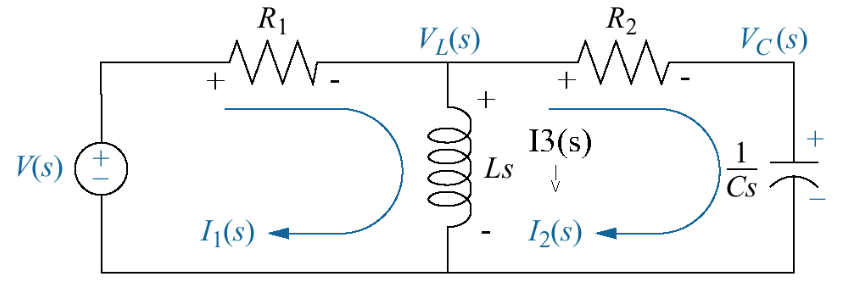

In class we solver this circuit using Mesh Analysis to get the tranfer function $\frac{I_2(s)}{V(s)}$. 

Now we will use Nodal analysis and Matlab to solve for the transfer function $\frac{V_C(s)}{V(s)}$.

If we know the voltage $V_L(s)$, then we can solve for any other quantity of interest easily. In our case we are interested in $V_C(s)$.

If we have already solved for $V_L(s)$ then the current 

$I_2(s)=\frac{V_L(s)}{R_2+\frac{1}{Cs}}$  and then $V_C(s)=I_2(s) \frac{1}{Cs}$

We will now use Kirkoff's Current Law to write down the equation for the currents leaving node in the middle of the top of the curcuit where $V_L(s)$ is written.


$$\frac{V_L-V}{R_1}+\frac{V_L}{Ls}+\frac{V_L}{{R_2+\frac{1}{Cs}}}=0$$


Solve for $V_L$:


$$\left (\frac{1}{R_1}+\frac{1}{Ls}+\frac{1}{R_2+\frac{1}{Cs}}\right )V_L=\frac{V}{R_1}\\
\left(\frac{Ls\left(R_2+\frac{1}{Cs}\right)+R_1\left(R_2+\frac{1}{Cs}\right)+R_1Ls}{R_1Ls\left(R_2+\frac{1}{Cs}\right)}\right)V_L=\frac{V}{R_1}
$$


Multiply LHS by $\frac{Cs}{Cs}$ to get


$$\left(\frac{Ls\left(R_2Cs+1\right)+R_1\left(R_2Cs+1\right)+R_1LCs^2}{R_1Ls\left(R_2Cs+1\right)}\right)V_L=\frac{V}{R_1}
$$


Collect powers of $s$:


$$\left(\frac{\left(R_1+R_2\right)LCs^2+\left(L+R_1R_2C\right)s+R_1}{R_1Ls\left(R_2Cs+1\right)}\right)V_L=\frac{V}{R_1}
$$


Solving for $V_L$ we get:


$$V_L=\left(\frac{R_1Ls\left(R_2Cs+1\right)}{\left(R_1+R_2\right)LCs^2+\left(L+R_1R_2C\right)s+R_1}\right)\frac{V}{R_1}
$$


Canceling $R_1$ on the RHS we get:


$$V_L=\left(\frac{Ls\left(R_2Cs+1\right)}{\left(R_1+R_2\right)LCs^2+\left(L+R_1R_2C\right)s+R_1}\right)V$$


Now we can use the voltage divider law to get:


$$V_C=V_L\left(\frac{\frac{1}{Cs}}{R_2+\frac{1}{Cs}}\right )\\
=\frac{V_L}{R_2Cs+1}\\
=\left(\frac{Ls\left(R_2Cs+1\right)}{\left(R_1+R_2\right)LCs^2+\left(L+R_1R_2C\right)s+R_1}\right)V\left(\frac{1}{R_2Cs+1}\right )$$


Canceling $(R_2Cs+1)$ we get:


$$V_c=\left(\frac{Ls}{\left(R_1+R_2\right)LCs^2+\left(L+R_1R_2C\right)s+R_1}\right)V$$


So we get the transfer function:


$$G(s)=\frac{V_c(s)}{V(s)}=\frac{Ls}{\left(R_1+R_2\right)LCs^2+\left(L+R_1R_2C\right)s+R_1}$$


How would we use Matlab to do the above algebraic manipulations?

clear
syms s I_2 R_1 R_2 C L V V_L V_C
V_L = solve((V_L-V)/R_1+V_L/(L*s)+V_L/(R_2+1/(C*s)) == 0,V_L)
%V_L(s)=simplifyFraction(V_L(s),'Expand',true)
V_L=collect(V_L)
V_C(s)=V_L*((1/(C*s))/(R_2+1/(C*s)))
G(s)=collect(V_C(s)/V)

OK. So this is definitely faster than doing it by hand once you know the Matlab commands!

**2. System Modeling: Electric Circuits (20 marks)**

a) (5 marks) Redraw the circuit with the components replaced by their Laplace domain impedances.

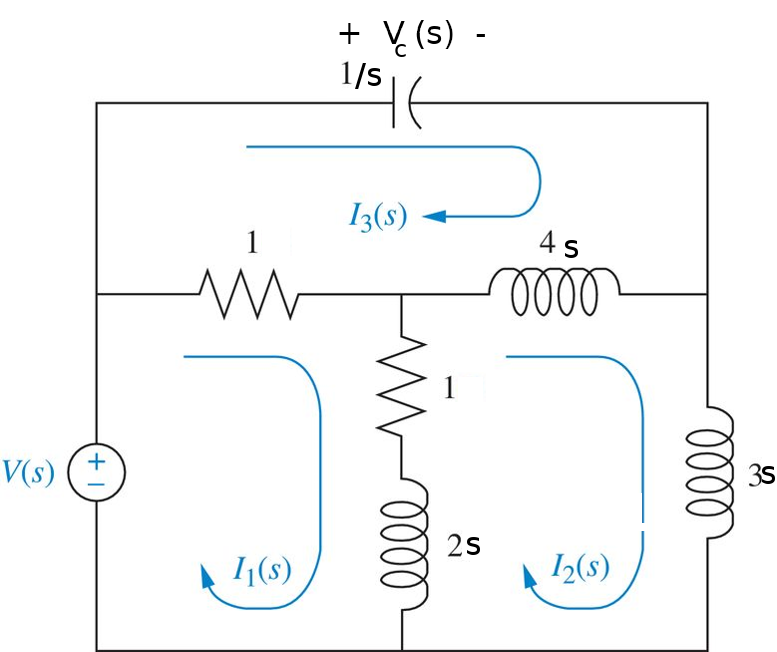

b) (5 marks) Write down the loop equation(s) that you would solve for the circuit including the equation for the output $V_C (s)$.

For Loop 1 (Bottom LHS of circuit)

clear
syms s I_1 I_2 I_3 V_c V
LoopEq1= 1*(I_1 - I_3) + (2*s + 1)*(I_1 - I_2) == V
LoopEq1=collect(collect(LoopEq1, I_2),I_1)

For Loop 2(Bottom RHS of circuit)

LoopEq2=(2*s + 1)*(I_2 - I_1) + 4*s*(I_2 - I_3) + 3*s*I_2 == 0
LoopEq2=collect(collect(LoopEq2, I_2),I_1)

For Loop 3(Top of circuit)

LoopEq3=I_3+4*s*(I_3-I_2)+ 1*(I_3-I_2)==0

Output equation:

LoopOutput=V_c==I_3/s

c) (5 marks) Write down the node equation(s) that you would use to solve for the transfer function from the input $V$ to the output $V_C$.

syms s V_A V_B V
NodeEqn1=(V_A-V)/1 + V_A/(2*s+1) + (V_A-V_B)/(4*s)==0
NodeEqn1=collect(NodeEqn1,V_A)
NodeEqn1=collect(NodeEqn1+V,V_A)
NodeEqn2=(V_B-V)/(1/s)+(V_B-V_A)/(4*s)+V_B/(3*s)==0
NodeEqn2=collect(NodeEqn2,V)
NodeEqn2=collect(collect(NodeEqn2,V_B),V_A)

Output equation is:

V_c=V-V_B

d) (5 marks) Find the transfer function $G(s)=\frac{V_C(s)}{V(s)}$.

eqns = [NodeEqn1, NodeEqn2];
vars = [V_A, V_B];
NodeSoln=solve(eqns,vars)
NodeSoln.V_B
G_n_V_C=collect((V-NodeSoln.V_B)/V)


Now let's try a mechanical system.

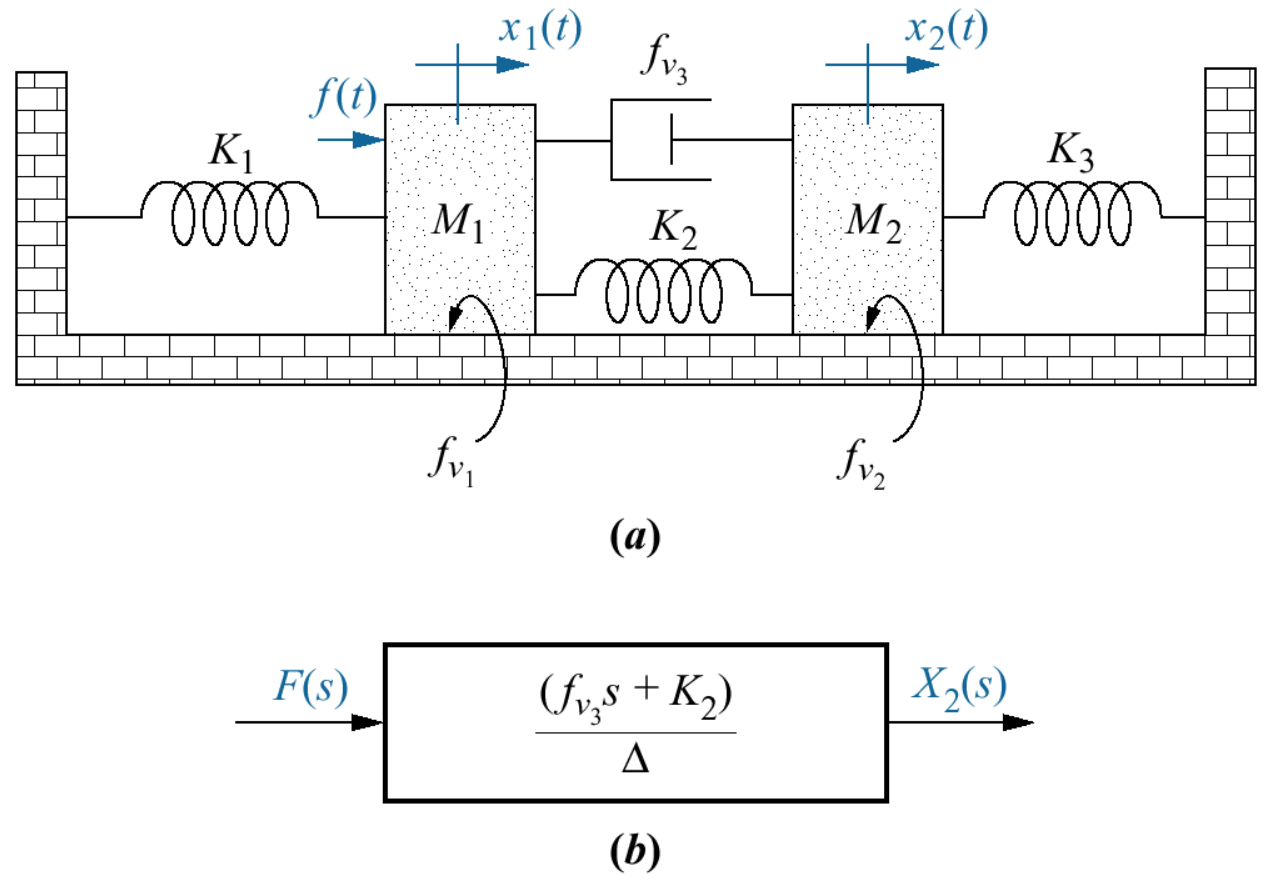

clear
syms s X_1 X_2 F(s) K_1 K_2 K_3 f_v_1 f_v_2 f_v_3 M_1 M_2

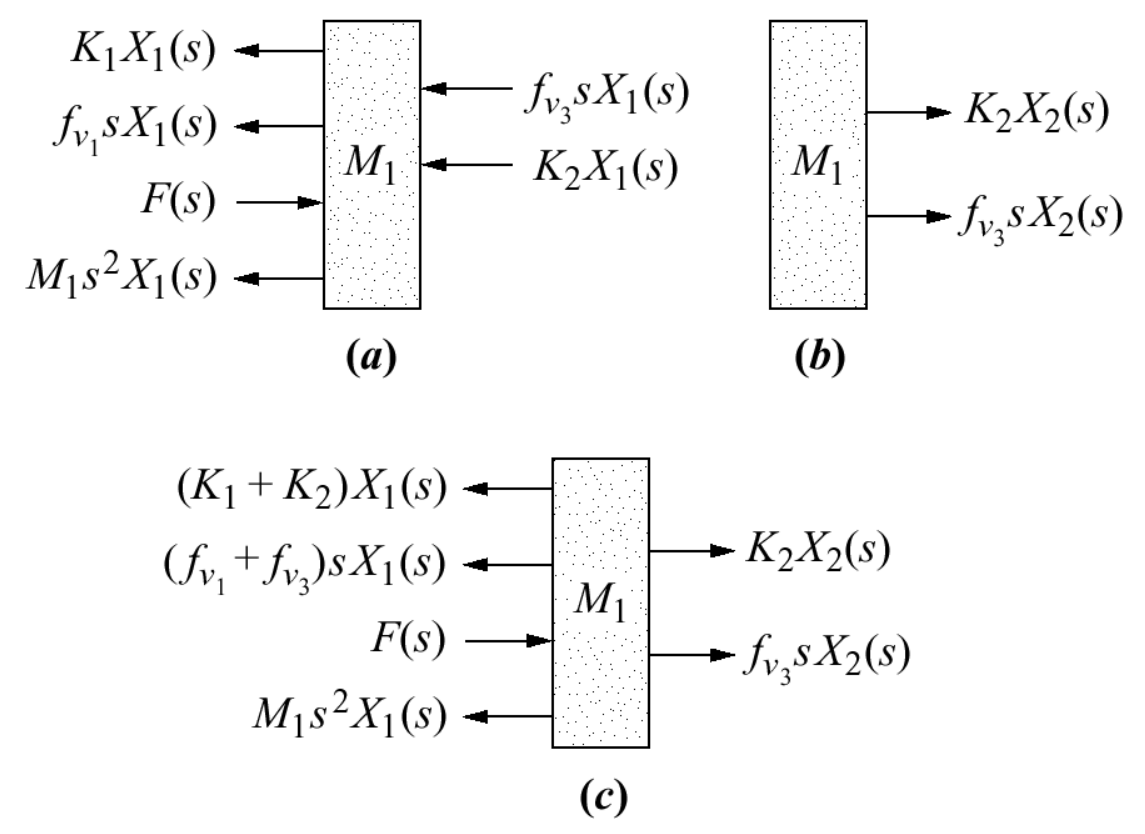

eq1 = K_1*X_1+K_2*X_1+f_v_1*s*X_1+f_v_3*s*X_1+M_1*s^2*X_1 == F(s)+K_2*X_2+f_v_3*s*X_2

Now consider $M_2$.

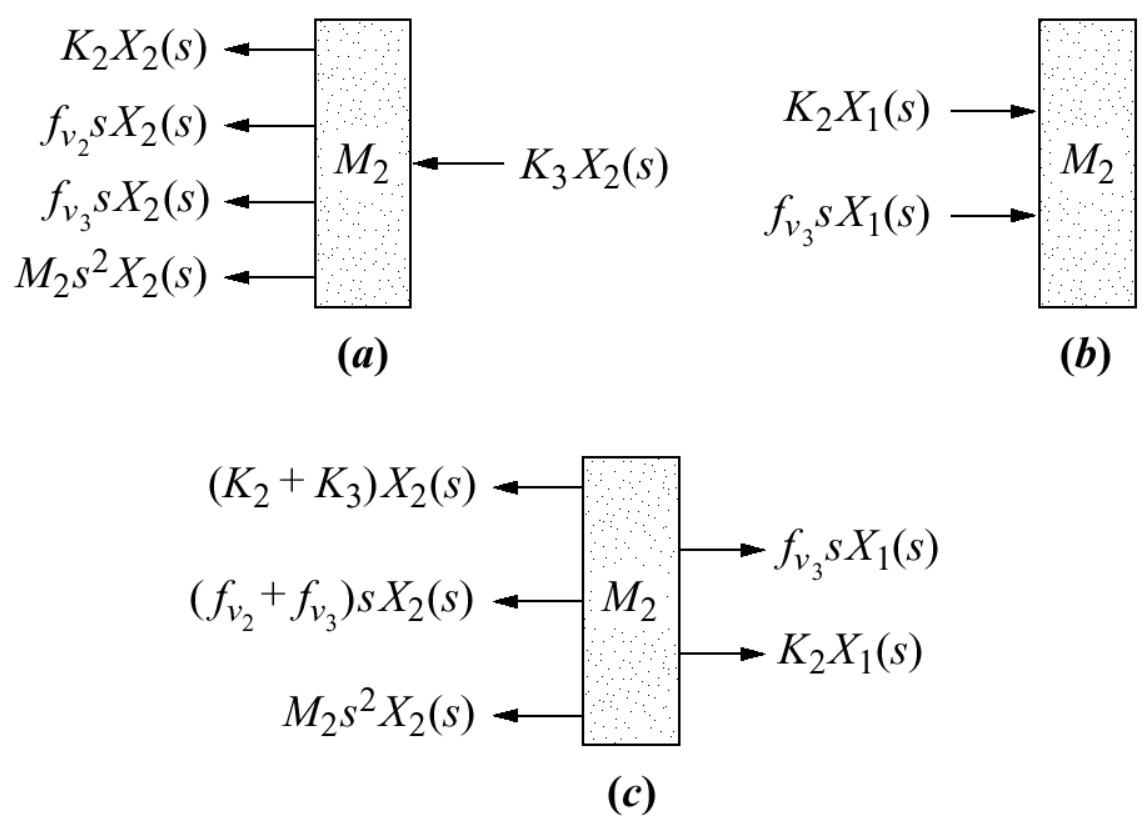

eq2 = (K_1+K_2)*X_2+(f_v_2+f_v_3)*s*X_2+M_2*s^2*X_2 == f_v_3*s*X_1+K_2*X_1
solns=solve([eq1,eq2],[X_1,X_2])
G_2=collect(solns.X_2/F(s))

Alternatively, rather than using the "solve" command I could have done Cramer's rule to solve for transfer function $G_2(s)=\frac{X_2(s)}{F(s)}$.

To do this let 


$$\mathbf{x}=\left [\begin{array}{c} X_1(s)\\X_2(s)\end{array}\right ]$$


Then eq1 and eq2 can be written in matrix for $\mathbf{Ax}=\mathbf{b}$. First let's clean up the equations to help put them in the right format:

eq1=collect(collect(eq1,X_2),X_1)
eq1=isolate(eq1,F(s))
eq2=collect(collect(eq2,X_1),X_2)
A=[M_1*s^2 + f_v_1*s + f_v_3*s + K_1+K_2  -(f_v_3*s + K_2); -(f_v_3*s + K_2)  M_2*s^2+(f_v_2+f_v_3)*s+(K_1 + K_2)]

and


b=[F(s);0]

Alternatively rather than manually writing down the equations in matrix format we can use Matlab's $\texttt{equationsToMatrix}$ command to do this automatically and eliminate the possibility of making a manaul error in copying!

[A,b]=equationsToMatrix([eq1,eq2],[X_1,X_2])

Then $X_2(s)=\frac{\det \mathbf{A}_2}{\det \mathbf{A}}$ where $A_2$ is the matrix obtained by replacing the 2nd column of $\mathbf{A}$ by $\mathbf{b}$. In matlab we can construc $\mathbf{A}_2$ as follows:

A_2=[A(:,1) b]

so we can now solve for $X_2(s)$ as

X_2=det(A_2)/det(A)

Then we get $G_2(s)=\frac{X_2(s)}{F(s)$ where we use the collect function to collect powers of $s$.

G_2alt=collect(X_2/F(s))

Check if it is the same answer as the other way we solved for it:

G_2-G_2alt

Looks like we did both calculations correctly.

#### Rotational Transfer Functions

Consider the example from Fig. 2.22

syms D_1 D_2 K J_1 J_2 T theta_1 theta_2 s
A=[J_1*s^2+ D_1*s+K     -K;
    -K               J_2*s^2+ D_2*s+K ]
collect(det(A))
B=[T;0]
A2=[A(:,1) B]
theta_2=collect(det(A2)/det(A))
theta_2/T

### Linearization

Consider an inverted pendulum

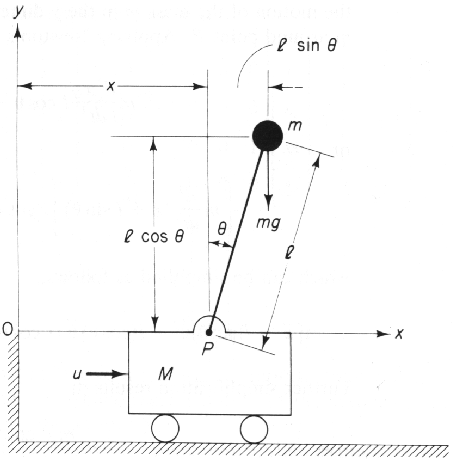

syms l m M g t u(t) theta(t) x(t)
eq1 = m*l^2*(diff(theta(t), t, t)) == m*g*l*sin(theta(t))-m*l*(diff(x(t), t, t))*cos(theta(t))
eq2 = u(t) == M*(diff(x(t), t, t))+m*(diff(x(t)+l*sin(theta(t)), t, t))

Now solve for the derivatives

syms x_1 x_2 x_3 x_4 x_5 x_6 v
eq3=subs(eq1,[diff(x,2),diff(theta,2)],[x_5,x_6])
eq4=subs(eq2,[diff(x,2),diff(theta,2)],[x_5,x_6])
secondDerivatives = solve([eq3, eq4], [x_5, x_6])
f_2=secondDerivatives.x_5
f_4=secondDerivatives.x_6
f_1=x_2
f_3=x_4
f_2=subs(f_2, [x,diff(x),theta,diff(theta),u],[x_1,x_2,x_3,x_4,v])
f_4=subs(f_4, [x,diff(x),theta,diff(theta),u],[x_1,x_2,x_3,x_4,v])
F=[f_1;f_2;f_3;f_4]

at equilibrium point $\mathbf{x}_o = \mathbf{0}, u_o = 0$.

Jx=jacobian(F,[x_1 x_2 x_3 x_4])
A=subs(Jx,[x_1 x_2 x_3 x_4 v],[0 0 0 0 0])
Jv=jacobian(F,v)
B=subs(Jv,[x_1 x_2 x_3 x_4 v],[0 0 0 0 0])


## Chapter 5: Block Diagram Reductions

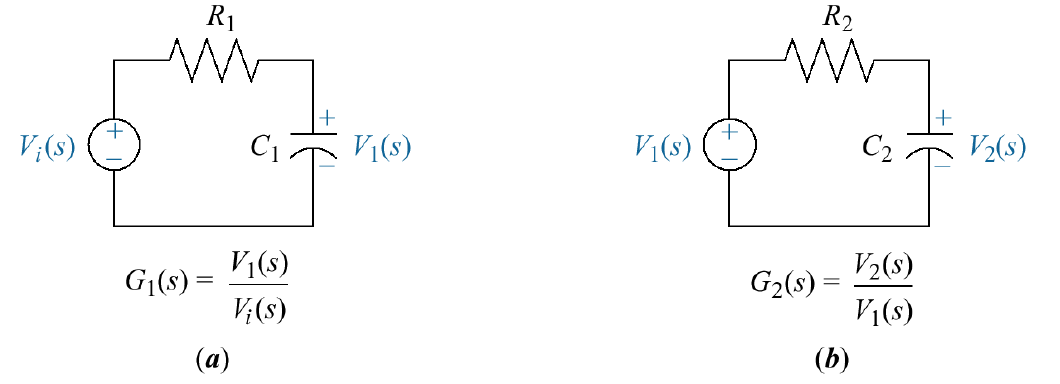

Consider the transfer functions for Fig (a) and (b) above $G_1(s)=\frac{V_1(s)}{V_i(s)}$ and $G_2=\frac{V_2(s)}{V_1(s)}$

clear
syms s Vi R1 C1 R2 C2 V1 V2 I1 I2

You can easily show that 

G1=1/(R1*C1*s+1)
G2=1/(R2*C2*s+1)

So you might think that for the circuit shown below, the transfer function $G(s)=\frac{V_2(s)}{V_i(s)}$

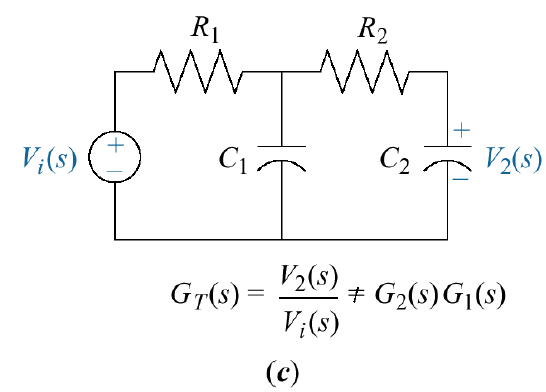

is given by:

G1*G2
G_Tnoload=collect(ans)

But this is ***NOT*** the case due to "loading". In computing the transfer function for circuit (a) $G_1(s)$ in measuring the voltage $V_1(s)$ at its output, we implicitly assume that the current flowing through $R_1$ is the same as the current flowing through $C_1$ but in the combined circuit shown in (c ) if we define the currents flowing left to right through resistors $R_1$and $R_2$ are $I_1$ and $I2$ respectively, we now have that the current flowing through $C_1$ top to bottom is $I_1-I_2$. That change in current caused by the loss of $I_2$ is the "load" placed on the first $G_1(s)$ stage of our cascaded transfer functions. So if sta   


R1*I1+1/(C1*s)*(I1-I2)==Vi 
eq1=collect(collect(ans,I2),I1)
R2*I2+1/(C2*s)*I2+1/(C1*s)*(I2-I1)==0
eq2=collect(collect(ans,I2),I1)
soln=solve([eq1,eq2],[I1,I2])

Note that $I_2(s)\neq 0$

collect(soln.I2)

V2==1/(C2*s)*soln.I2
G_T=collect(rhs(ans)/Vi)

is the actual transfer function whereas the ideal transfer function with no loading is

G_Tnoload

So the transfer functions differ by a factor of $C_2R_1s$ in the denominator. So if $R_2>>R_1$(i.e. the input impedance of stage 2 is much bigger than the output impedance of stage 1, then this gets closer to the ideal situation,

**Block DIagram Reduction**

Example from Fig. 5.9

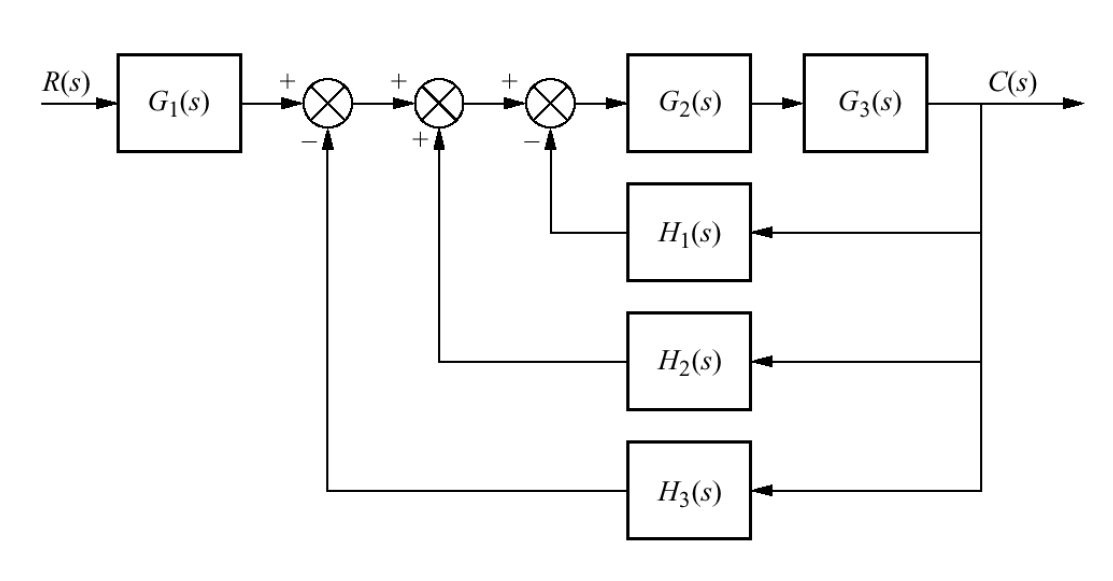

**Method 1:** Verifying step-by-step manual block diagram manipulations

syms G_1 G_2 G_3 H_1 H_2 H_3

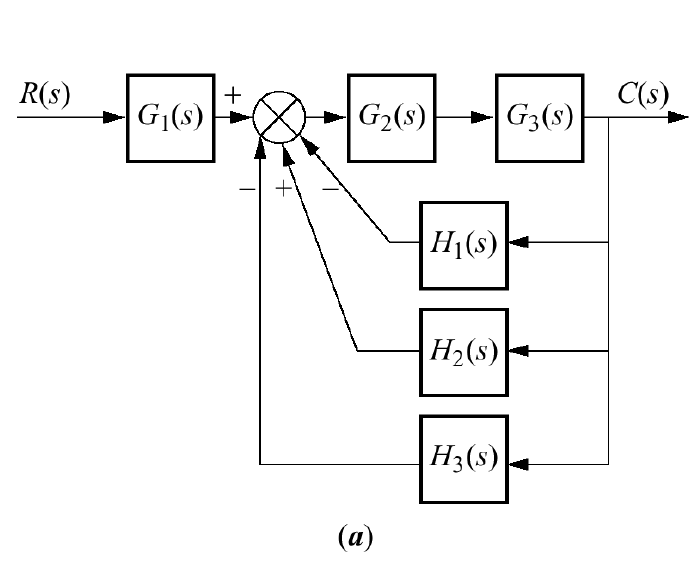

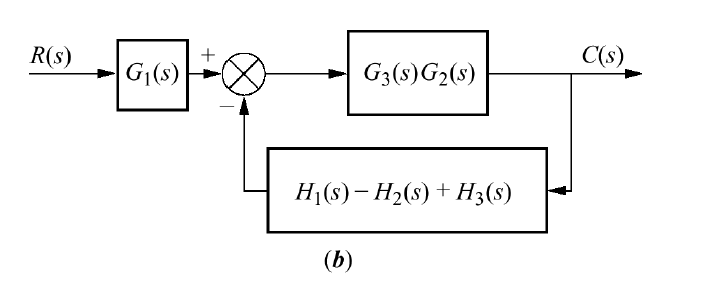

Collapse the feedback loop:

G=G_2*G_3
H=H_1-H_2+H_3
G_collapse=G/(1+G*H)

Now we have $G_1$ in cascade with $G_\textit{collapse}$ so the final equvalent block diagram is:

G_eq=G_1*G_collapse

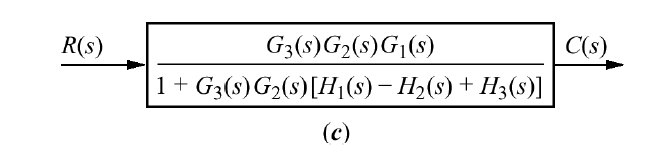

**Method 2**: Define state variables $x_1, x_2, x_3$ at the output of each summing junction and write down equations and solve

syms X_1 X_2 X_3 C R
eq1 = X_1 == G_1*R-H_3*C
eq2 = X_2 == X_1+H_2*C
eq3 = X_3 == X_2-H_1*C
eqC = C == G_2*G_3*X_3
BDsoln=solve([eq1,eq2,eq3,eqC],[X_1,X_2,X_3,C])
G_cl=BDsoln.C/R
%[A,B]=equationsToMatrix([eq1,eq2,eq3,eq4],[X_1,X_2,X_3,X_4])
collect(G_cl-G_eq)
G_cl-G_eq

**Block Diagram Reduction** (20 marks) (From 2020 Midterm)

Consider the block diagram below:

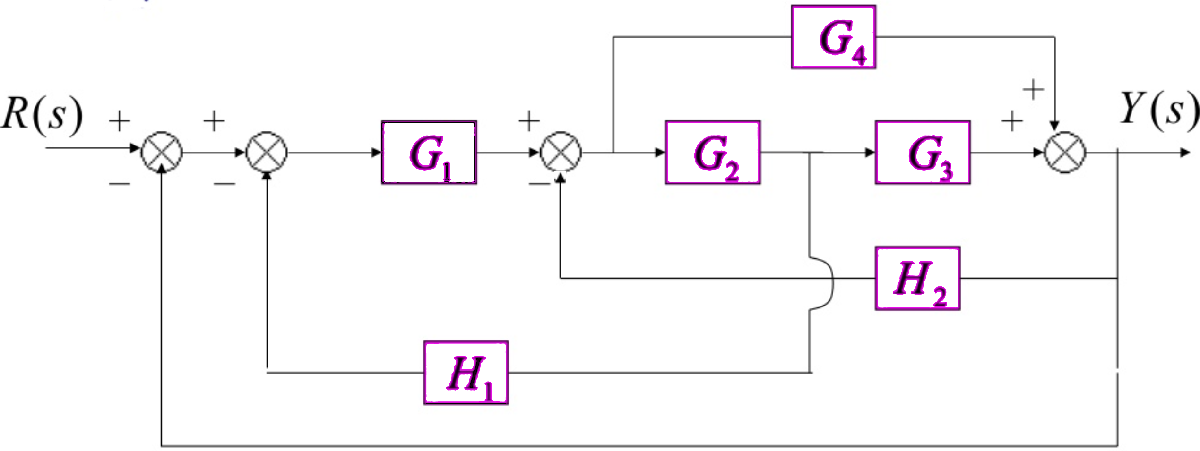

What is the closed loop transfer function $G_{cl}(s)=\frac{Y(s)}{R(s)}$?

Start by moving pickoff point from A to B as shown below:

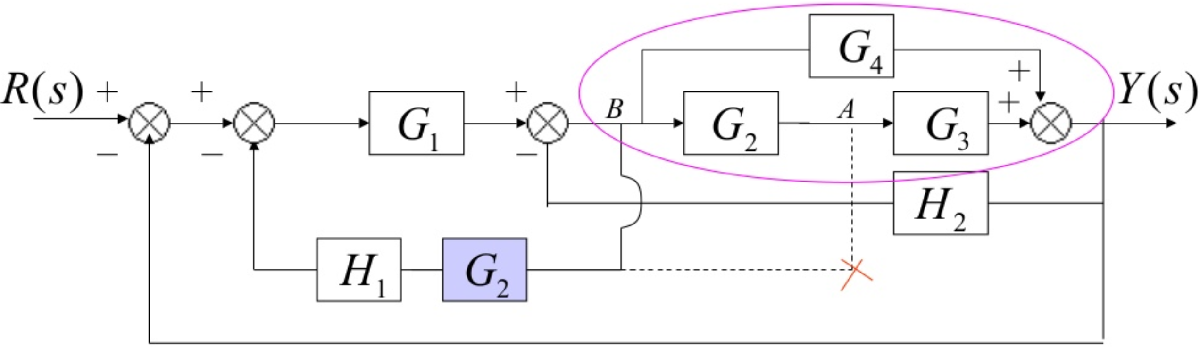

Reduce parallel blocks $G_4||G_2G_3$ and combine sequential blocks $H_1$ and $G_2$ to get:

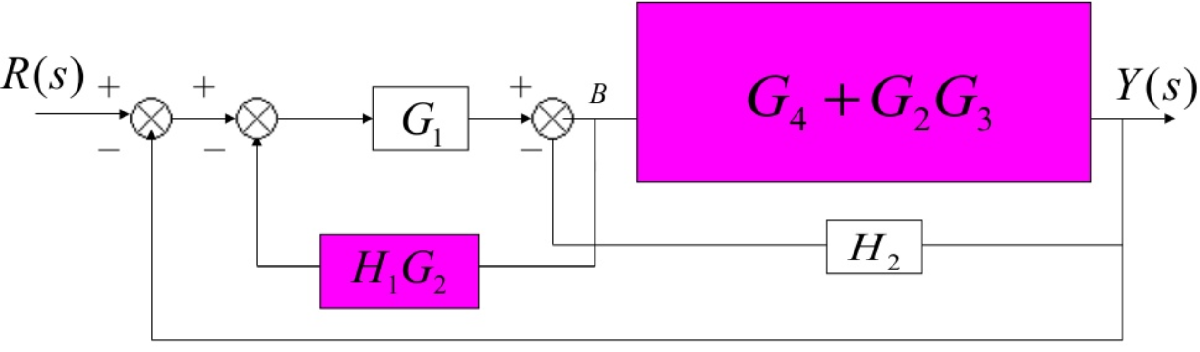

Move pickoff point $B$ to the other side of the $G_4+G_2G_3$ block.

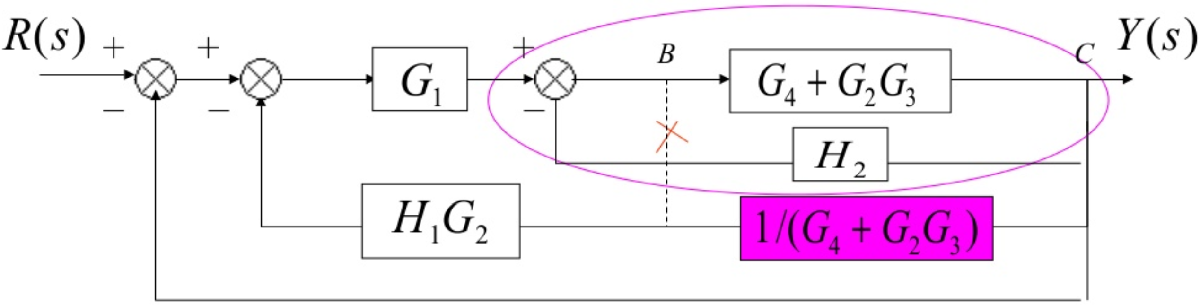

Collapse the feedbacklook circled above:

Method 1 (Checking hand calculations)

clear
syms G_1 G_2 G_3 G_4 H_1 H_2
G_FB1=(G_4+G_2*G_3)/(1+(G_4+G_2*G_3)*H_2)

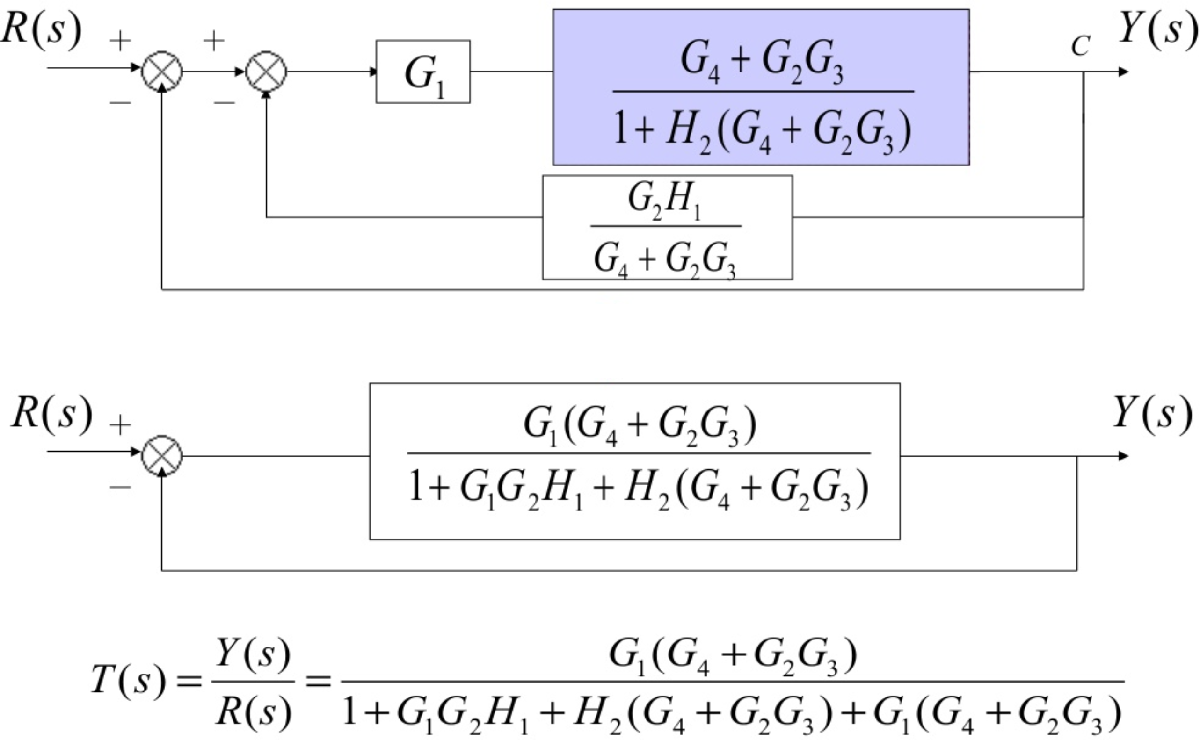

Collapsing the inner feedback look you get:

G_FB2=G_1*G_FB1/(1+G_1*G_FB1*(G_2*H_1)/(G_4+G_2*G_3))
G_2FB=collect(G_FB2)
G_cl=G_FB2/(1+G_FB2)
G_cl=collect(G_cl)

**Method 2:**

Assign variables $X_1, X_2, X_3$ to the outputs of the first 3 summing junctions from left to right

syms R G_1 G_2 G_3 G_4 H_1 H_2 Y X_1 X_2 X_3
eq1=X_1==R-Y
eq2=X_2==X_1-G_2*H_1*X_3
eq3=X_3==G_1*X_2-H_2*Y
eq4=Y==G_2*G_3*X_3+G_4*X_3
BDsoln=solve([eq1,eq2,eq3,eq4],[X_1,X_2,X_3,Y])
G_cl2=BDsoln.Y/R
%[A,B]=equationsToMatrix([eq1,eq2,eq3,eq4],[X_1,X_2,X_3,X_4])
collect(G_cl-G_cl2)